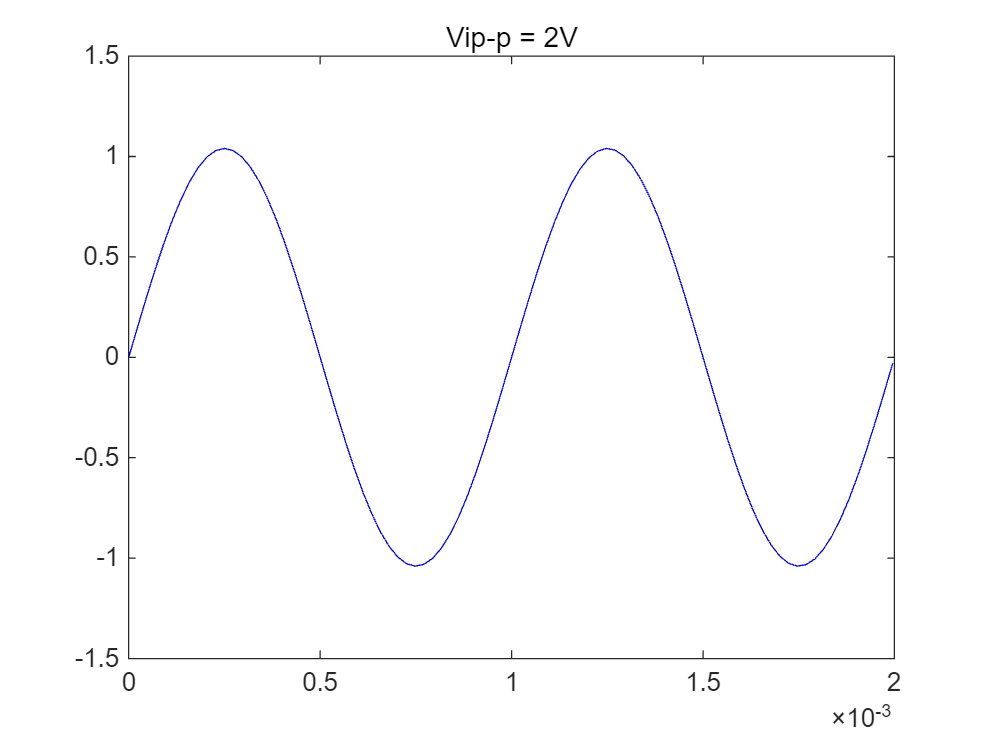

% % 参数设置
% t = 0:1;                % 时间向量 (从0到1秒)
% f = 1000;                       % 正弦波的频率 (Hz)
% A = 1;                       % 正弦波幅度
% clipLevel = 0.8;             % 上限限幅电平
% 
% % 计算正弦波
% y = A*sin(2*pi*f*t);
Fs = 44100;
duration = 0.002;               % 正弦波的持续时间 (秒)
t = 0:1/Fs:duration;           % 时间向量
f = 1000;                      % 正弦波的频率 (Hz)
A = 1.04;
% 生成正弦波
y1 = A*sin(2*pi*f*t);

y2 = 2.08*sin(2*pi*f*t);

y3 = 4.08*sin(2*pi*f*t);
cliplevel3 = 3.60;
y3_clipped = min(y3, cliplevel3);

y4 = 5.12*sin(2*pi*f*t);
cliplevel4 = 3.68;
y4_clipped = min(y4,cliplevel4);

y5 = 6.16*sin(2*pi*f*t);
cliplevel5 = 3.76;
y5_clipped = min(y5,cliplevel5);

y6 = 6.64*sin(2*pi*f*t);
y6_clipped = min(y6,cliplevel5);

y7 = 6.72*sin(2*pi*f*t);
y7_clipped = min(y7,cliplevel5);

figure;
plot(t, y1, 'b-'); hold on;
title('Vip-p = 2V');

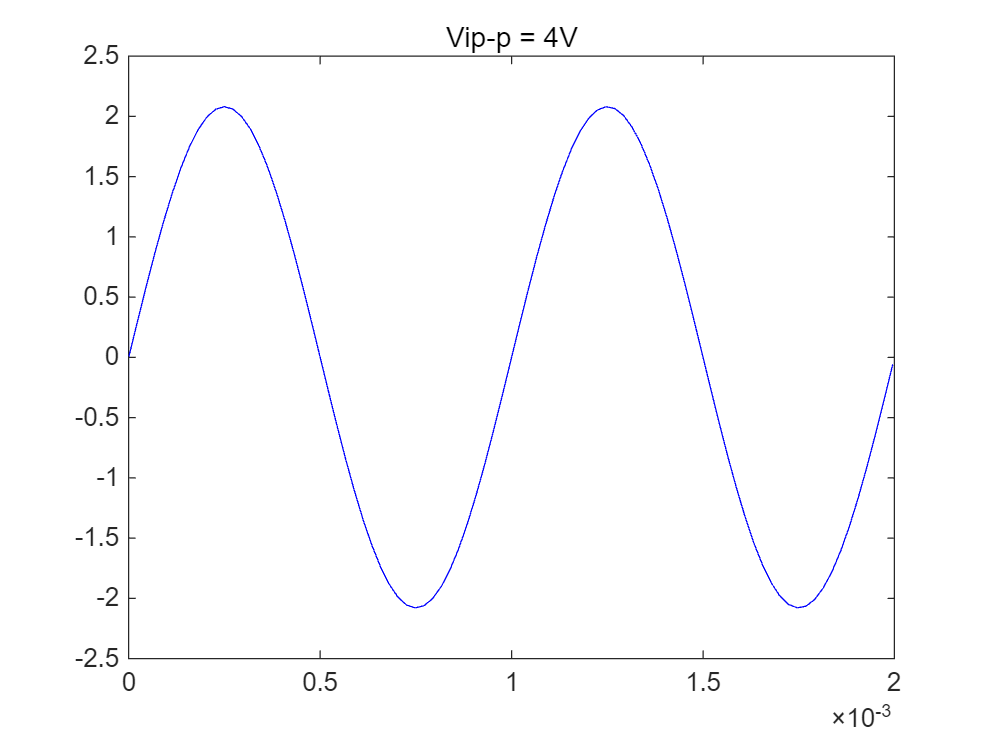

figure;
plot(t, y2, 'b-'); hold on;
title('Vip-p = 4V');

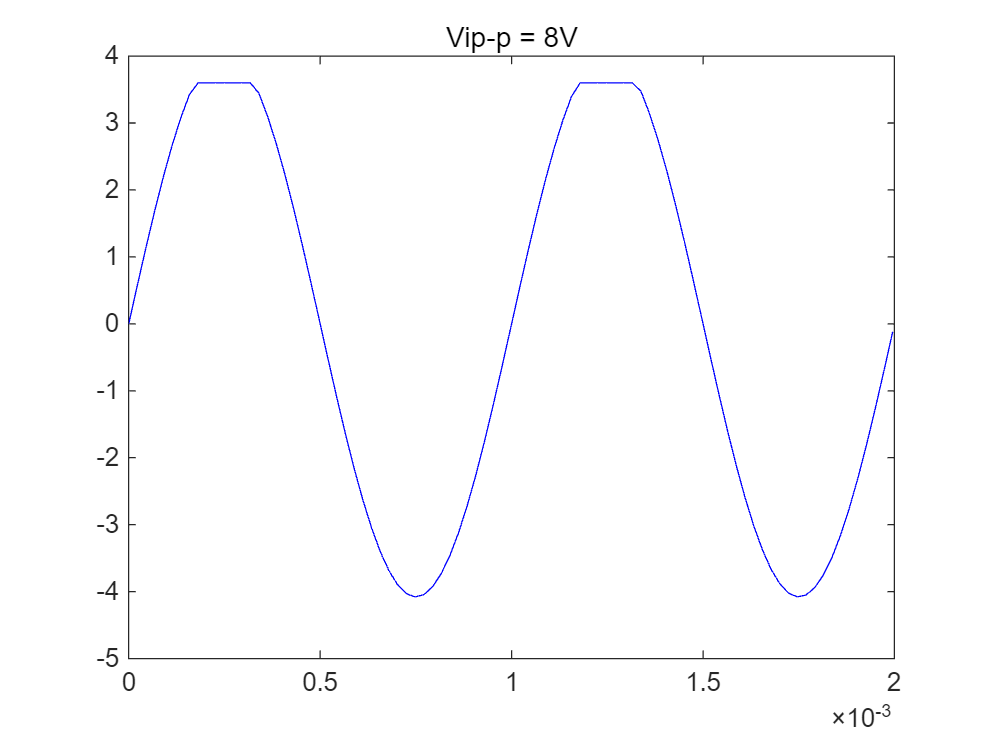

figure;
plot(t, y3_clipped,'b-');
title('Vip-p = 8V');

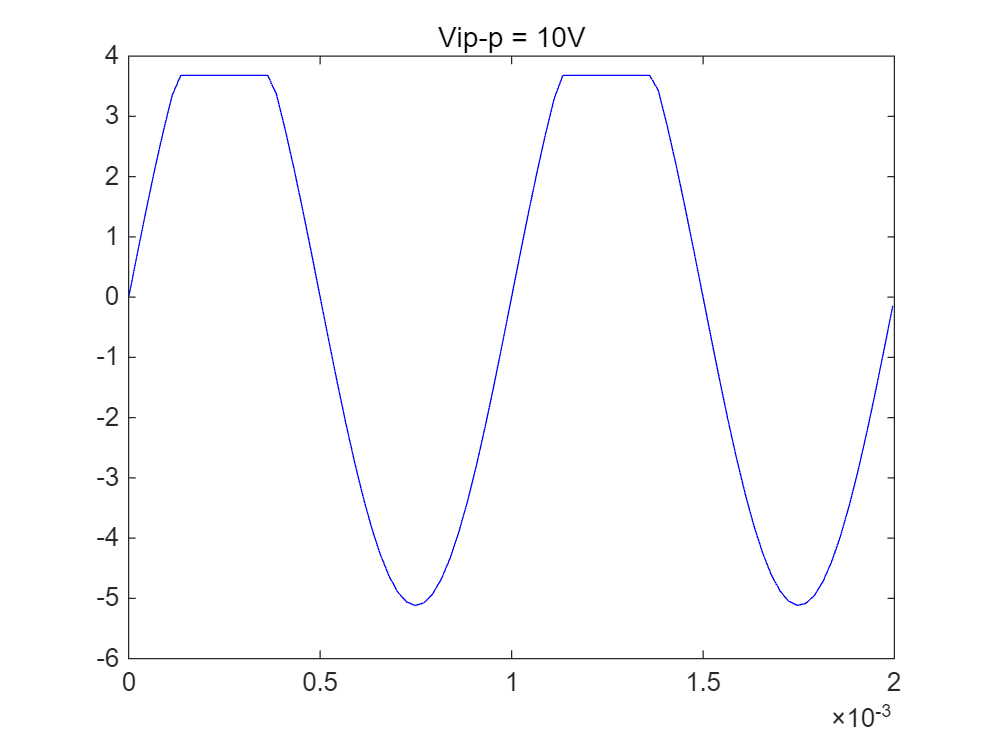

figure;
plot(t, y4_clipped,'b-');
title('Vip-p = 10V');

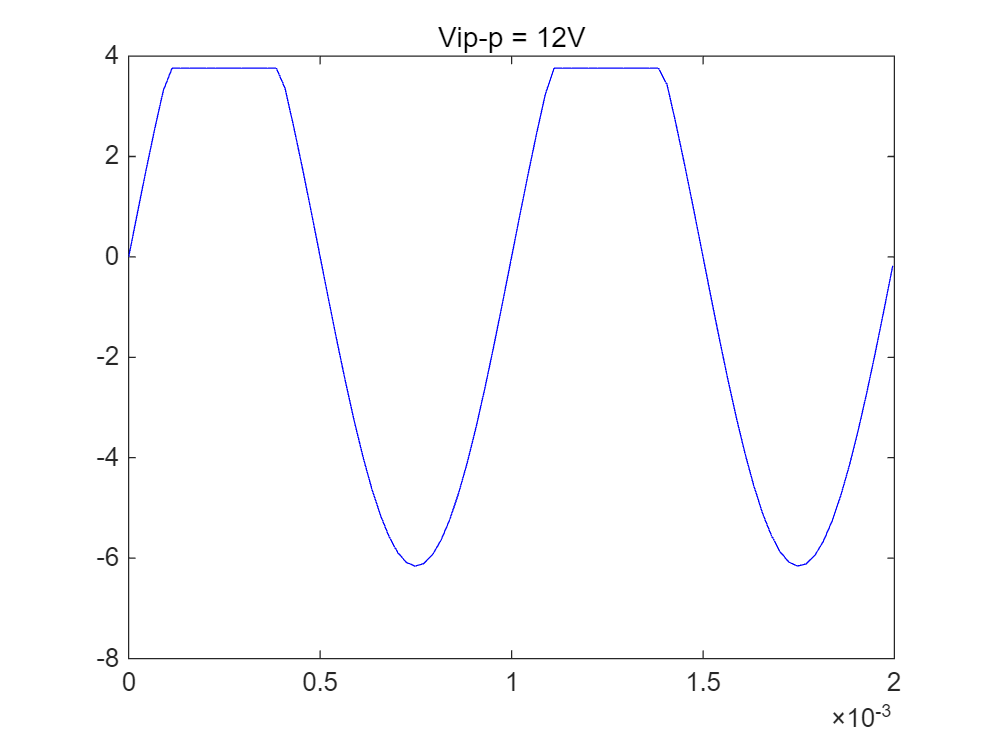

figure;
plot(t, y5_clipped,'b-');
title('Vip-p = 12V');

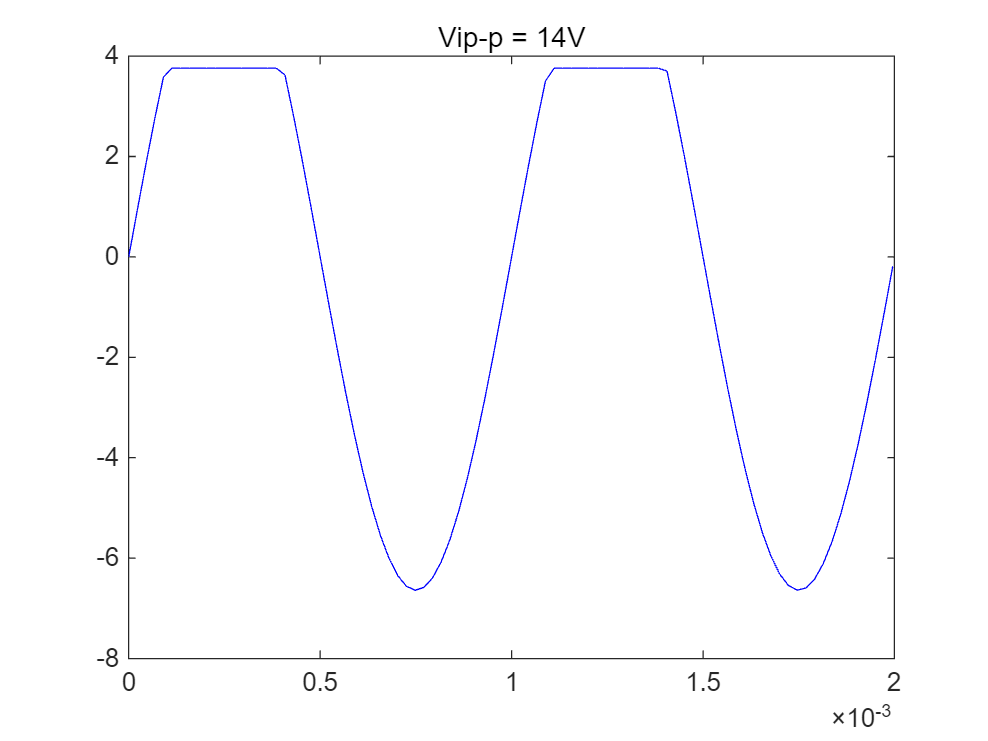

figure;
plot(t, y6_clipped,'b-');
title('Vip-p = 14V');

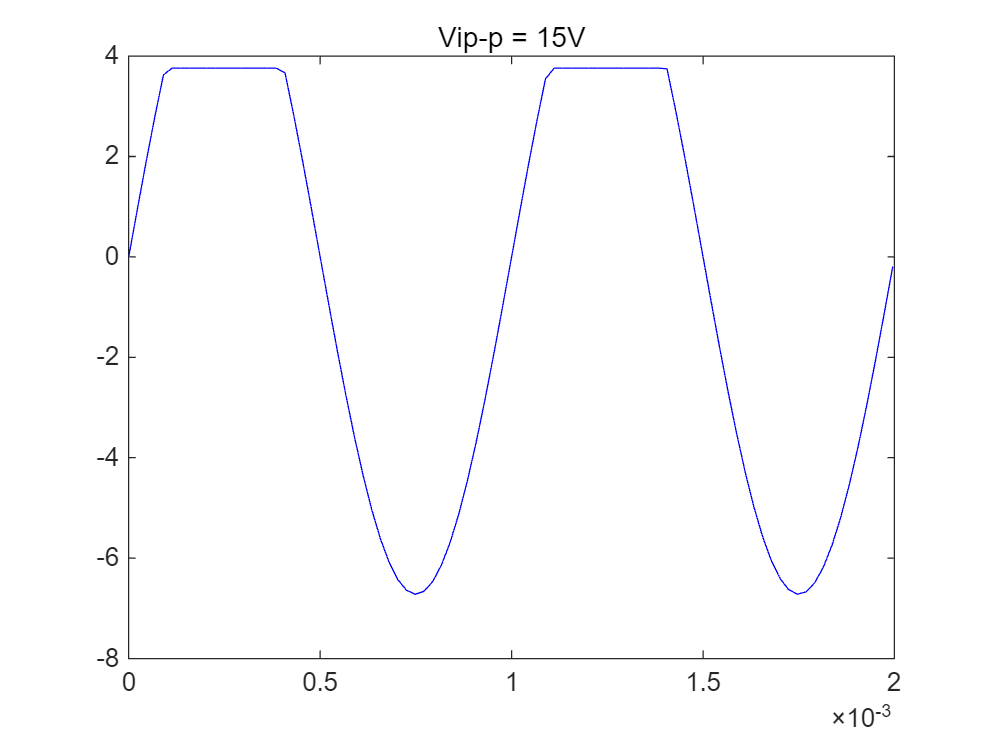

figure;
plot(t, y7_clipped,'b-');
title('Vip-p = 15V');




% 对正弦波进行上限限幅处理
% y_clipped = min(y, clipLevel)

% % 绘制原始和限幅后的正弦波
% figure;
% plot(t, y, 'b-', 'DisplayName', '原始正弦波'); hold on;
% plot(t, y_clipped, 'r-', 'DisplayName', '上限限幅正弦波');
% xlabel('时间 (秒)');
% ylabel('幅度');
% title('上限限幅正弦波');
% legend show; % 显示图例
% grid on;
% 
% % 如果需要同时限制下限，可以加上对负值部分的处理
% % 假设下限限幅电平为 -0.8
% lowerClipLevel = -0.8;
% y_clipped_full = max(min(y, clipLevel), lowerClipLevel);
% 
% % 另外绘制同时有上下限限幅的结果
% figure;
% plot(t, y, 'b-', 'DisplayName', '原始正弦波'); hold on;
% plot(t, y_clipped_full, 'g-', 'DisplayName', '上下限限幅正弦波');
% xlabel('时间 (秒)');
% ylabel('幅度');
% title('上下限限幅正弦波');
% legend show; % 显示图例
% grid on;